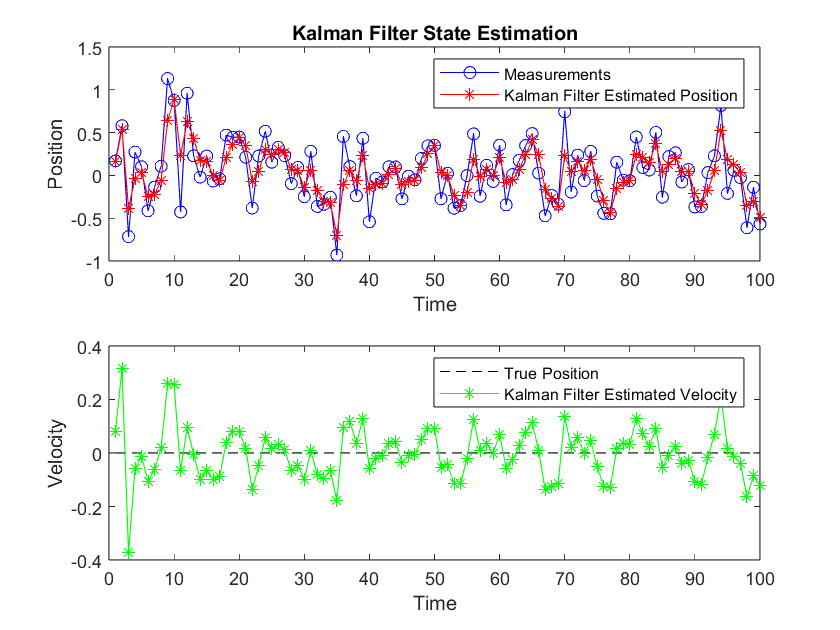

% Define the initial state estimate [position; velocity]
x_estimate = [0; 0];

% Define the initial estimate error covariance matrix
P = eye(2);

% Define the state transition matrix (constant velocity model)
A = [1, 1; 0, 1];

% Define the control input matrix (assuming no control input)
B = [0; 0];

% Define the process noise covariance matrix
Q = [0.01, 0; 0, 0.01];

% Define the measurement matrix (we directly measure the position)
H = [1, 0];

% Define the measurement noise covariance
R = 0.1;

% Define the initial state [position; velocity]
x_true = [0; 1];

% Simulate measurements (in practice, you would have real measurements)
num_measurements = 100;
measurements = x_true(1) + sqrt(R) * randn(1, num_measurements);

% Preallocate arrays to store results
x_estimates = zeros(2, num_measurements);
P_estimates = zeros(2, 2, num_measurements);

for k = 1:num_measurements
    % Prediction Step
    x_predict = A * x_estimate;
    P_predict = A * P * A' + Q;

    % Update Step
    K = P_predict * H' / (H * P_predict * H' + R);
    x_estimate = x_predict + K * (measurements(k) - H * x_predict);
    P = (eye(2) - K * H) * P_predict;

    % Store the estimates
    x_estimates(:, k) = x_estimate;
    P_estimates(:, :, k) = P;
end

% Plot the results
time = 1:num_measurements;
figure;
subplot(2, 1, 1);
plot(time, measurements, 'bo-', time, x_estimates(1, :), 'r*-');
legend('Measurements', 'Kalman Filter Estimated Position');
xlabel('Time');
ylabel('Position');
title('Kalman Filter State Estimation');

subplot(2, 1, 2);
plot(time, x_true(1) * ones(1, num_measurements), 'k--', time, x_estimates(2, :), 'g*-');
legend('True Position', 'Kalman Filter Estimated Velocity');
xlabel('Time');
ylabel('Velocity');